## Classification Analysis

Lily Jiang

Here are the accuracies for each of the 6 features I looked at:

#### Variance

validation_accuracy = 0.9037

train_accuracy = 0.9185

test_accuracy = 0.9556

#### RMS

validation_accuracy = 0.9556

train_accuracy = 0.9556

test_accuracy = 0.9778

#### MAV

validation_accuracy = 0.8889

train_accuracy = 0.9185

test_accuracy = 0.9556

#### WL

validation_accuracy = 0.9852

train_accuracy = 0.9852

test_accuracy = 0.9778

#### StDev

validation_accuracy = 0.9556

train_accuracy = 0.9556

test_accuracy = 1.0

#### Mean

validation_accuracy = 0.3259

train_accuracy = 0.4222

test_accuracy = 0.3556

Let's put this into code so we can plot the accuracies against each other:

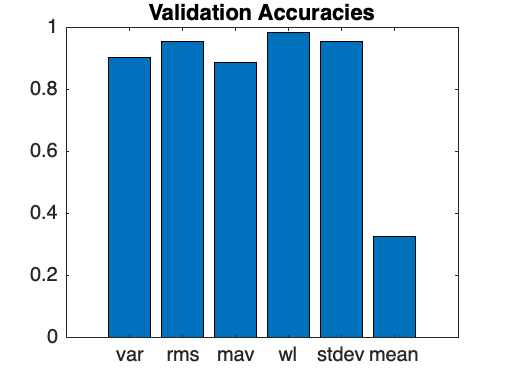

features = {'var','rms','mav','wl','stdev','mean'};

validation_accuracies = [0.9037 0.9556 0.8889 0.9852 0.9556 0.3259];
train_accuracies = [0.9185 0.9556 0.9185 0.9852 0.9556 0.4222];
test_accuracies = [0.9556 0.9778 0.9556 0.9778 1 0.3556];

figure();
bar(validation_accuracies);
set(gca,'xticklabel', features);
title('Validation Accuracies');

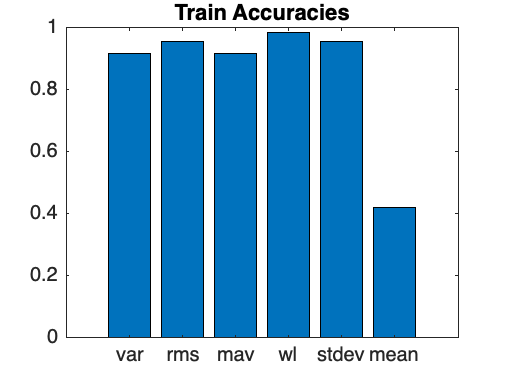


figure();
bar(train_accuracies);
set(gca,'xticklabel', features);
title('Train Accuracies');

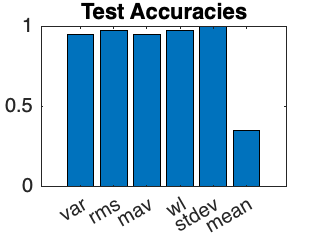


figure();
bar(test_accuracies);
set(gca,'xticklabel', features);
title('Test Accuracies');

#### Final Model

Based on the bar plots, the 2 features I like best are Wavelength and Standard Deviation.

I'll use these 2 features to build a "final" model. This is run in `OfflineClassificationFromFeatures.mlx`, and I'm just changing the line

`selected_features = [1 2 3 4];`

to be:

`selected_features = [13 14 15 16 17 18 19 20];`

I've also written a function to calculate the F1 score based on a confusion matrix. Because it's a 3x3 confusion chart (and therefore doesn't fall into the True/False dynamic), I found the F1 score for each of the 3 classes, then took the average of the values.

function [F1] = calculateF1(CM)
    TP1 = CM(1, 1);
    FN1 = CM(1, 2) + CM(1, 3);
    FP1 = CM(2, 1) + CM(3, 1);
    % TN1 = CM(2, 2) + CM(2, 3) + CM(3, 2) + CM(3, 3);
    TP2 = CM(2, 2);
    FN2 = CM(2, 1) + CM(2, 3);
    FP2 = CM(1, 2) + CM(3, 2);
    TP3 = CM(3, 3);
    FN3 = CM(1, 3) + CM(2, 3);
    FP3 = CM(3, 1) + CM(3, 2);
    
    precision1 = TP1 / (TP1 + FP1);
    recall1 = TP1 / (TP1 + FN1);
    precision2 = TP2 / (TP2 + FP2);
    recall2 = TP2 / (TP2 + FN2);
    precision3 = TP3 / (TP3 + FP3);
    recall3 = TP3 / (TP3 + FN3);

    F1_1 = 2 * (precision1 * recall1) / (precision1 + recall1);
    F1_2 = 2 * (precision2 * recall2) / (precision2 + recall2);
    F1_3 = 2 * (precision3 * recall3) / (precision3 + recall3);
    
    F1 = (F1_1 + F1_2 + F1_3) / 3;
end